# **Creating an MDP MATLAB Environment with a Q learning Agent**

## Problem Formulation

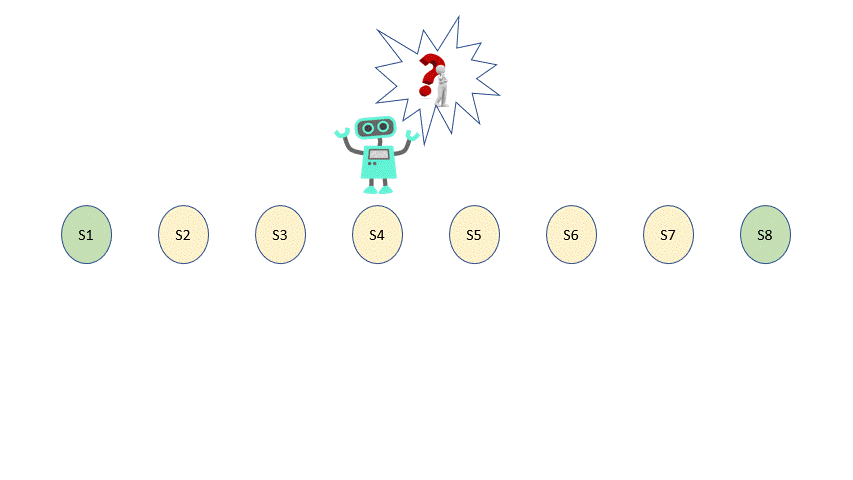

***GOAL****:-* Reach to the *nearest terminal point* *as quickly as possible*

***Action:-***  The agent can either move towards left or right

***States:*** A total of 8 states with 2 terminal states and 6 non terminal states

***Reward:*** All nonterminal states have a small negative reward and terminal states have a large positive reward

***Assumptions:***

- Agent has to move around, cannot stop at one place.

- All actions are deterministic and result into exact execution.

## **Creating an MDP Model**

- We begin by creating parameters which would be used later at multiple places.

- We would need to have values for States, Actions, Reward and Transition Probabilities

%States ~~  code on line 2
States= 8 ;

% Actions an agent can take ~~ code on line 5
Actions= ["left", "right"]; 

%Reward for Non-terminal States ~~ code on line 8
RewardNT = -1 ;

%Reward for Terminal States ~~ code on line 11
RewardT = 10 ;

%Transition Probability is 1 for all action ~~ code on line 8
Transition_Probability = 1;

**TASK: Create an MDP object and store it in a variable named MDP**

- Use function [`createMDP(states,actions)`](https://www.mathworks.com/help/reinforcement-learning/ref/createmdp.html#d123e1992)`,`which takes in 2 inputs.

- States signifies number of states in the environment ~~ which is defined on line 2

- Actions signifies list of possible actions ~~ which is defined on line 5

%%%%% Start your code here %%%% ~ 1 line
MDP = createMDP(States,Actions)

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [0×1 string]


%%%%% Code ends here %%%%

**Q1: Show the states of the MDP Model**

**Q2: Show the actions of the MDP Model**

%%%%% Start your code here %%%% ~ 2 lines
MDP.States

ans = 8×1 string array
    "s1"
    "s2"
    "s3"
    "s4"
    "s5"
    "s6"
    "s7"
    "s8"


MDP.Actions

ans = 2×1 string array
    "left"
    "right"



%%%%% Code ends here %%%%

**Q3: Show the Transition Probability of the MDP Model**

%%%%% Start your code here %%%% ~ 1 line
MDP.T

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,2) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


%%%%% Code ends here %%%%

T — State transition matrix, specified as a 3-D array, which determines the possible movements of the agent in an environment.

State transition matrix T is a probability matrix that indicates how likely the agent will move from the current state s to any possible next state s' by performing action a. T is given by, T s, s′, a   =  probability s′ s, a

Eg:- Probability of transitioning from State 2 to State 3 is represented by an element in row 2 and column 3

**Q4: Show the Reward of the MDP Model** 

%%%%% Start your code here %%%% ~ 1 line
MDP.R

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,2) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


%%%%% Code ends here %%%%

R —  Reward transition matrix, specified as a 3-D array, determines how much reward the agent receives after performing an action in the environment. R has the same shape and size as state transition matrix T. Reward transition matrix R is given by, r  =  R s, s′, a .

## Modify and Define Terminal States, Rewards and Transition Probabilities as per given the model

#### **Q5: Update Terminal states of variable MDP**

- State 1 and 8 [S1 and S8] are the terminal state.

%%%%% Start your code here %%%% ~ 1 line
MDP.TerminalStates = ["s1";"s8"]

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [2×1 string]


%%%%% Code ends here %%%%

**Q6: Store Non Terminal state in a variable named NonTerminalstates**

-  Get the data in MDP.States that is not in MDP.TerminalStates

- Use function [` setdiff(A,B)`](https://www.mathworks.com/help/matlab/ref/double.setdiff.html#d123e1301163)

%%%%% Start your code here %%%% ~ 1 line
NonTerminalStates= setdiff(MDP.States,MDP.TerminalStates)

NonTerminalStates = 6×1 string array
    "s2"
    "s3"
    "s4"
    "s5"
    "s6"
    "s7"


%%%%% Code ends here %%%%

#### Q7: Update the Reward array

- Begin with assigning reward of -1 for all the action in all the states 

%%%%% Start your code here %%%% ~ 1 line
MDP.R(:,:,:)= RewardNT

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [2×1 string]


%%%%% Code ends here %%%%

**Q8: Change the reward for Terminal state to value stored in the variable RewardNT**

- Use function state2idx

- `Converts a state name into an index -- special function for MDP Object`

%%%%% Start your code here %%%% ~ 1 line
MDP.R(:,state2idx(MDP,MDP.TerminalStates),:)= RewardT

MDP =   GenericMDP with properties:

      CurrentState: "s1"
            States: [8×1 string]
           Actions: [2×1 string]
                 T: [8×8×2 double]
                 R: [8×8×2 double]
    TerminalStates: [2×1 string]


%%%%% Code ends here %%%%

#### Q9: Modify the transition probability matrix as per the given model

- Recall the definition of Transition Probability - T s, s′, a   =  probability s′ s, a

- Meaning, the probability of being in a state s and going into a state s' by taking action A

- Begin with visualizing Transition Probability Matrix again

MDP.T

ans = ans(:,:,1) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


ans(:,:,2) =

     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0


-  If the agent is in the state 1 then it should land in state 2 by taking an action RIGHT.

- The agent lands in the same state if it takes action in the Terminal state that leads to nowhere.

**Q10: Try to update Transition Probabilities for the states**

% State 1 transition
MDP.T(1,1,1) = 1;
MDP.T(1,2,2) = 1;

% State 2 transition
MDP.T(2,1,1) = 1;
MDP.T(2,3,2) = 1;

% State 3 transition
MDP.T(3,2,1) = 1;
MDP.T(3,4,2) = 1;

% State 4 transition
MDP.T(4,3,1) = 1;
MDP.T(4,5,2) = 1;

% State 5 transition
MDP.T(5,4,1) = 1;
MDP.T(5,6,2) = 1;

% State 6 transition
MDP.T(6,5,1) = 1;
MDP.T(6,7,2) = 1;

% State 7 transition
MDP.T(7,6,1) = 1;
MDP.T(7,8,2) = 1;

% State 8 transition
MDP.T(8,7,1) = 1;
MDP.T(8,8,2) = 1;


## Displaying modified properties 

**Q11: Display the updated values of Transition Probabilities and Reward**

%%%%% Start your code here %%%% ~ 2 lines
MDP.R

ans = ans(:,:,1) =

    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10


ans(:,:,2) =

    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10
    10    -1    -1    -1    -1    -1    -1    10


MDP.T

ans = ans(:,:,1) =

     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0


ans(:,:,2) =

     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1
     0     0     0     0     0     0     0     1



%%%%% Code ends here %%%%

## Initialize Environment

**Q12: Create a Reinforcement Learning environment using the given function and MDP object created above. Store it in a variable named env**

- We use [`rlMDPEnv(MDP)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.rlmdpenv.html#d123e17882) to create an environment using the MDP object

%%%%% Start your code here %%%% ~ 1 line
env = rlMDPEnv(MDP)

env =   rlMDPEnv with properties:

       Model: [1×1 rl.env.GenericMDP]
    ResetFcn: []


%%%%% Code ends here %%%%

**Q13: Store the value of number of states in a variable named number_of_states**

**Q14: Store the value of number of actions in a variable named number_of_actions**

- We use built-in MATLAB function numel to get the values. [`n = numel(A)`](https://www.mathworks.com/help/matlab/ref/double.numel.html#d123e914058)

%%%%% Start your code here %%%% ~ 2 lines
number_of_states= numel(MDP.States)

number_of_states = 8

number_of_actions= numel(MDP.Actions)

number_of_actions = 2

%%%%% Code ends here %%%%

## Define Q-table and Initialize Agent

**Task**: Display the information of States in the environment

**Function**: [`getObservationInfo(env)`](https://www.mathworks.com/help/reinforcement-learning/ref/getobservationinfo.html#d123e6637)

**Input**: An RL Environment object

`Usage:` Obtain OBSERVATION/STATE data specifications from reinforcement learning environment or agent

%%%%% Start your code here %%%% ~ 1 line
state_information = getObservationInfo(env)

state_information =   rlFiniteSetSpec with properties:

       Elements: [8×1 double]
           Name: "MDP Observations"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


%%%%state_information% Code ends here %%%%

**Task**: Display the information of Actions in the environment

**Function**: [`getActionInfo(env)`](https://www.mathworks.com/help/reinforcement-learning/ref/getactioninfo.html#d123e3947)

**Input**: An RL Environment object

`Usage:` Obtain ACTION data specifications from reinforcement learning environment or agent

%%%%% Start your code here %%%% ~ 1 line
action_information = getActionInfo(env)

action_information =   rlFiniteSetSpec with properties:

       Elements: [2×1 double]
           Name: "MDP Actions"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


%%%%% Code ends here %%%%

We want to make use of Q-learning agent. A Q-learning agent is represented by observations from the environment (state) and action available. 

**Task:** first create a Q table using the observation in a varible name *qTable*

`Function:` [`rlTable(obsinfo,actinfo)`](https://www.mathworks.com/help/reinforcement-learning/ref/rltable.html#d123e25994)

**Inputs: **Number of states** (line 48)** and Number of actions (**line 50)**

%%%%% Start your code here %%%% ~ 1 line
qTable = rlTable(state_information,action_information)

qTable =   rlTable with properties:

    Table: [8×2 double]


%%%%% Code ends here %%%%

**Task: **Display the Q -table

%%%%% Start your code here %%%% ~ 1 line
qTable.Table

ans =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


%%%%% Code ends here %%%%

**Task:** Change all the values of q-table to 5

%%%%% Start your code here %%%% ~ 1 line
qTable.Table = ones(size(qTable.Table))*5

qTable =   rlTable with properties:

    Table: [8×2 double]


qTable.Table

ans =      5     5
     5     5
     5     5
     5     5
     5     5
     5     5
     5     5
     5     5


%%%%% Code ends here %%%%

**Task:** Create the Q-value function based `critic` (Brain of the agent) named as *qRepresentation*

**Function:** [`rlQValueRepresentation(tab,observationInfo,actionInfo)`](https://www.mathworks.com/help/reinforcement-learning/ref/rlqvaluerepresentation.html#d123e21104)

**Inputs:**

- q-value is a [`rlTable`](https://www.mathworks.com/help/reinforcement-learning/ref/rltable.html) object containing a table with as many rows as the possible observations and as many columns as the possible actions (**line 54)**

- State information **(line 48)**

- Action Information **(line 50)**

`Usage:`` Let MATLAB know that the table created will be used a Q-learning agent. Apply the Q-learning algorithm to this table while training.`

%%%%% Start your code here %%%% ~ 1 line
qRepresentation = rlQValueRepresentation(qTable,state_information,action_information)

qRepresentation =   rlQValueRepresentation with properties:

         ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
    ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
            Options: [1×1 rl.option.rlRepresentationOptions]


%%%%% Code ends here %%%%

**Task:** Display Options property of qRpresentation

%%%%% Start your code here %%%% ~ 1 line
qRepresentation.Options

ans =   rlRepresentationOptions with properties:

                  LearnRate: 0.0100
          GradientThreshold: Inf
    GradientThresholdMethod: "l2norm"
     L2RegularizationFactor: 1.0000e-04
                  UseDevice: "cpu"
                  Optimizer: "adam"
        OptimizerParameters: [1×1 rl.option.OptimizerParameters]


%%%%% Code ends here %%%%

During each control interval the agent selects a random action with probability ϵ, otherwise it selects an action greedily with respect to the value function with probability 1-ϵ. This greedy action is the action for which the value function is greatest. 

qRepresentation.Options.L2RegularizationFactor=0;
qRepresentation.Options.LearnRate = 0.01;

Task: Create a variable named *agentOpts* to store and specifiy parameters for updating q-values

Function: [`rlQAgentOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rlqagentoptions.html).

Assign agentOpts = function

Inputs: No inputs

%%%%% Start your code here %%%% ~ 1 line
agentOpts = rlQAgentOptions

agentOpts =   rlQAgentOptions with properties:

    EpsilonGreedyExploration: [1×1 rl.option.EpsilonGreedyExploration]
                  SampleTime: 1
              DiscountFactor: 0.9900


%%%%% Code ends here %%%%

**Task:** Display epsilon greeedy exploration property

%%%%% Start your code here %%%% ~ 1 line
agentOpts.EpsilonGreedyExploration

ans =   EpsilonGreedyExploration with properties:

    EpsilonDecay: 0.0050
         Epsilon: 1
      EpsilonMin: 0.0100


%%%%% Code ends here %%%%

**Task:** Change EpsilonDecay to 0.01

%%%%% Start your code here %%%% ~ 1 line
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 0.01

agentOpts =   rlQAgentOptions with properties:

    EpsilonGreedyExploration: [1×1 rl.option.EpsilonGreedyExploration]
                  SampleTime: 1
              DiscountFactor: 0.9900


%%%%% Code ends here %%%%

Task: create a Q-learning agent named *qAgent* using this Q-table representation and configuration of the epsilon-greedy exploration. 

`Function: `[`rlQAgent(critic,agentOptions)`](https://www.mathworks.com/help/reinforcement-learning/ref/rlqagent.html#d123e22434)

`Inputs:`

- `critic (Brain if the agent) (``line 63)`

- `agentOpts (Learning and equation parameters)`` (line 70)`

%%%%% Start your code here %%%% ~ 1 line
qAgent = rlQAgent(qRepresentation,agentOpts)

qAgent =   rlQAgent with properties:

    AgentOptions: [1×1 rl.option.rlQAgentOptions]


%%%%% Code ends here %%%%

## Train Agent

Task: specify the training parameters in a variable name *trainOpts*

Function: [`rlTrainingOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rltrainingoptions.html).

%%%%% Start your code here %%%% ~ 1 line
trainOpts = rlTrainingOptions

trainOpts =   rlTrainingOptions with properties:

                   MaxEpisodes: 500
            MaxStepsPerEpisode: 500
    ScoreAveragingWindowLength: 5
          StopTrainingCriteria: "AverageSteps"
             StopTrainingValue: 500
             SaveAgentCriteria: "none"
                SaveAgentValue: "none"
            SaveAgentDirectory: "savedAgents"
                       Verbose: 0
                         Plots: "training-progress"
                   StopOnError: "on"
                   UseParallel: 0
        ParallelizationOptions: [1×1 rl.option.ParallelTraining]


%%%%% Code ends here %%%%

trainOpts.MaxStepsPerEpisode = 10;
trainOpts.MaxEpisodes = 100;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 13;
trainOpts.ScoreAveragingWindowLength = 30;

QTable0 = getLearnableParameters(getCritic(qAgent));
disp(QTable0{1})

     5     5
     5     5
     5     5
     5     5
     5     5
     5     5
     5     5
     5     5



## Begin Training

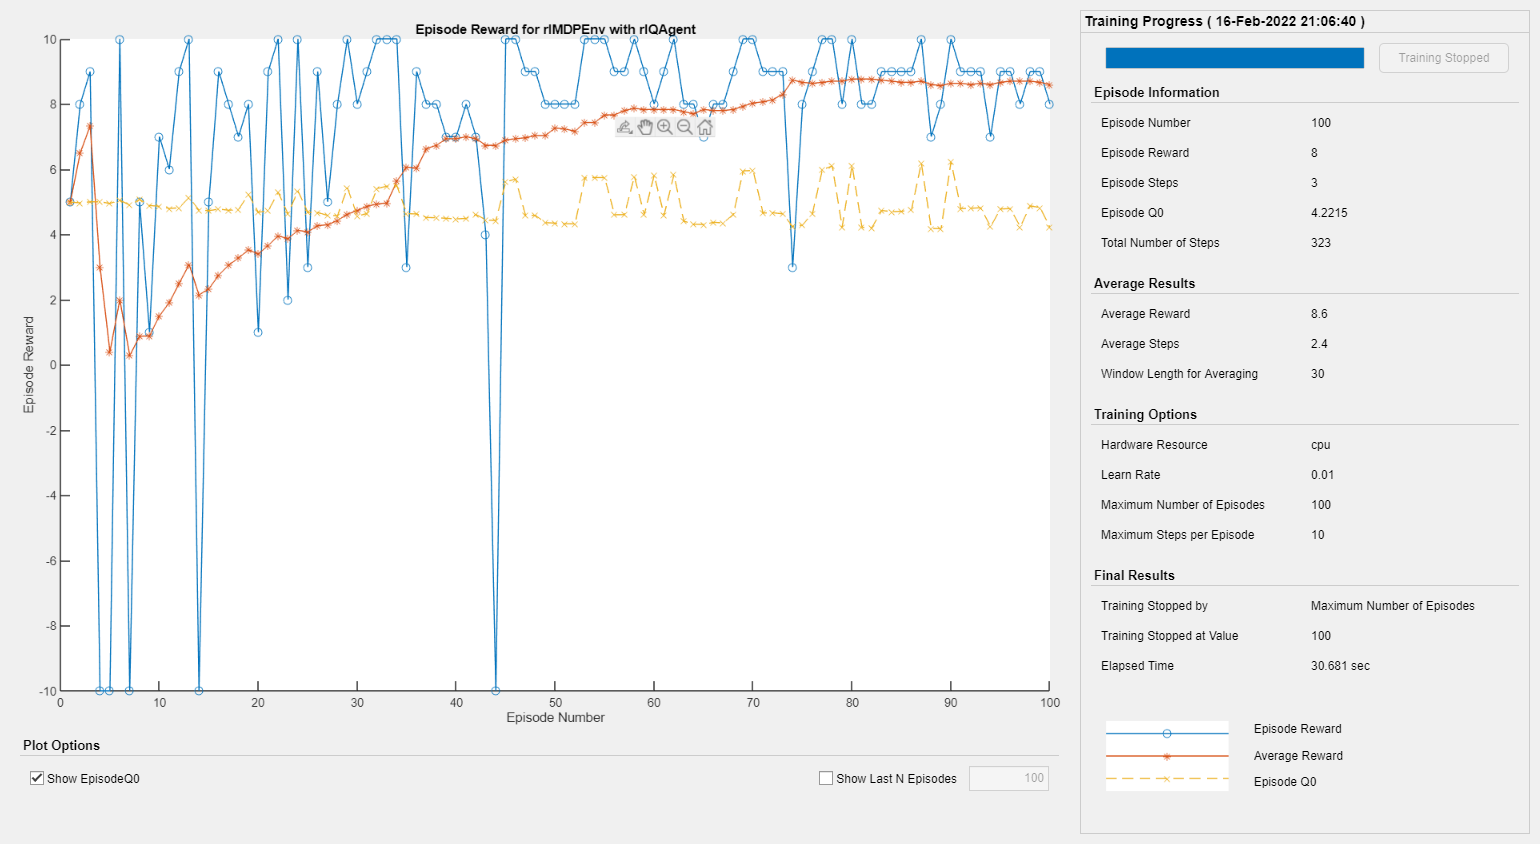

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(qAgent,env,trainOpts); %#ok<UNRCH> 
else
    % Load pretrained agent for the example.
    load('genericMDPQAgent.mat','qAgent'); 
end

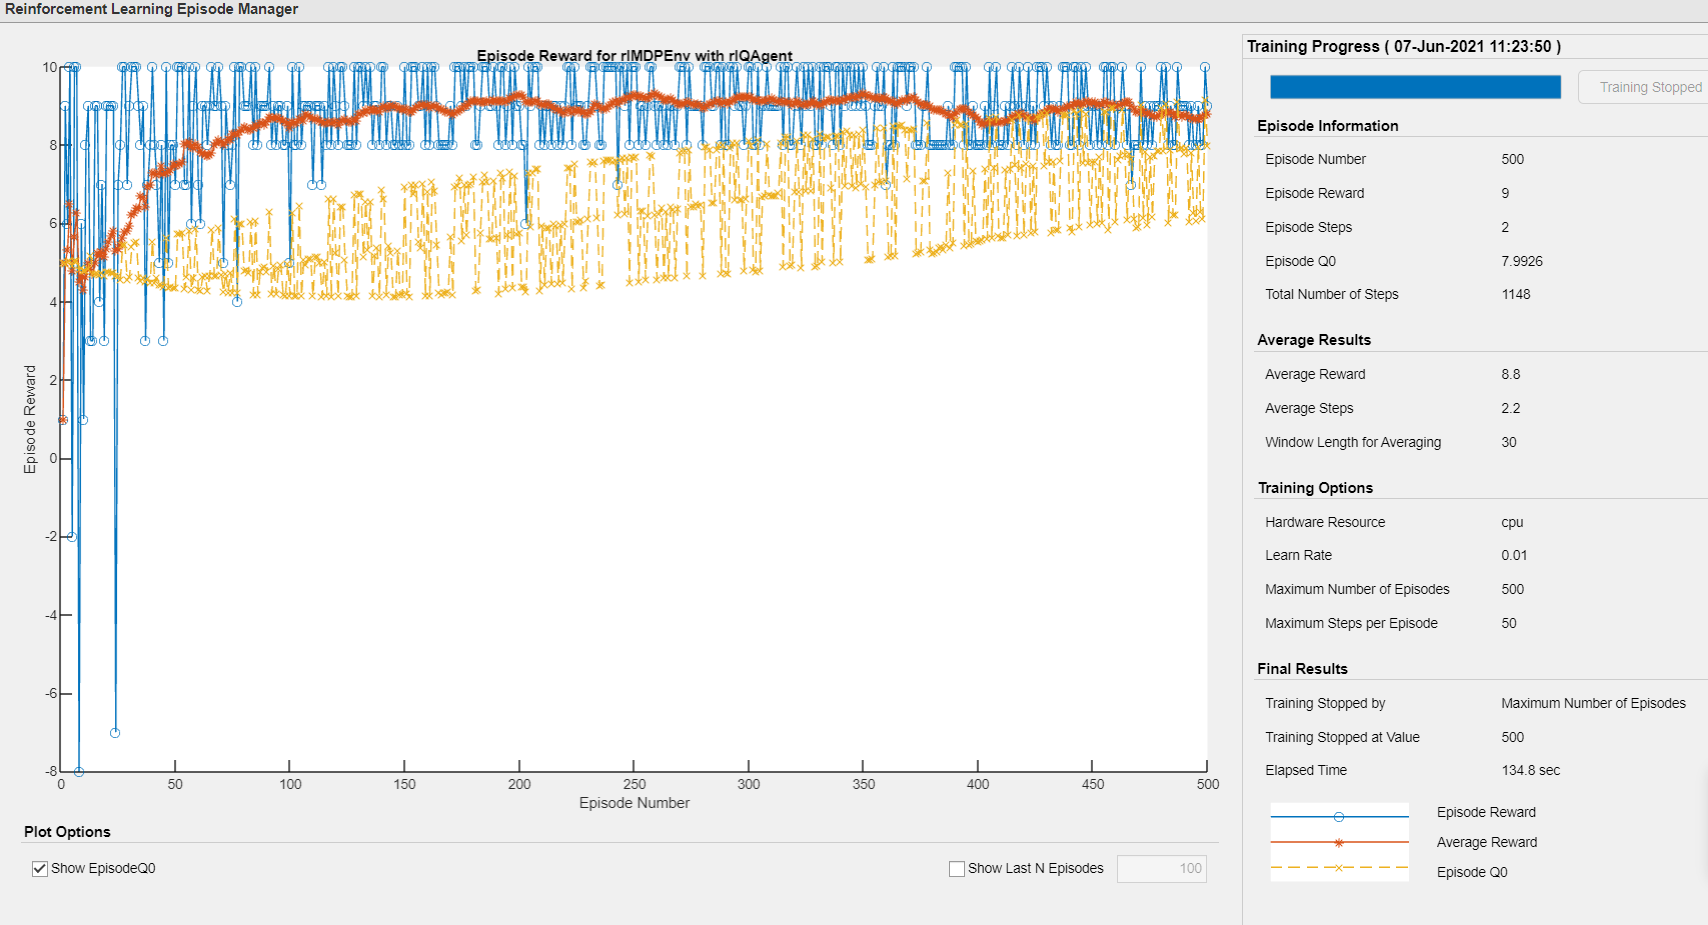

Store trained agent's properties in a varaible called Data. We do this to access and make use of the training solutions,

Data = sim(qAgent,env)

Data = struct with fields:
       Observation: [1×1 struct]
            Action: [1×1 struct]
            Reward: [1×1 timeseries]
            IsDone: [1×1 timeseries]
    SimulationInfo: [1×1 struct]


cumulativeReward = sum(Data.Reward)

cumulativeReward = 7

Obtain learnable parameter values from policy or value function representation: [`getLearnableParameters(rep)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.representation.rlabstractrepresentation.getlearnableparameters.html#d123e4326)

`getLearnableParameters(`[`rep`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.representation.rlabstractrepresentation.getlearnableparameters.html#mw_c4339311-2eb9-4291-8a3e-8593bf2d6c8c)`)` returns the values of the learnable parameters from the reinforcement learning policy or value function representation `rep`.

QTable = getLearnableParameters(getCritic(qAgent));
QTable{1}

ans =     5.0000    5.0000
    6.3718    4.8348
    4.9033    4.5692
    4.2215    4.2194
    4.1543    4.1466
    4.5253    4.8322
    4.6767    6.2420
    5.0000    5.0000
